## **Feature Manipulation Experiment 5**

**In this notebook we will create a SHH containing three solvers: **

**1) HH1: A hyper-heuristic containing LPT and SPT **

**2) HH3: A hyper-heuristic containing MPA and LPA**

**3) MPA **

**This experiment is very similar to the one before, we only need to add one instance to the set of instances and one solver to the SHH model. **

**The set of instances for this experiment containg 5 instances: the first 4 instances are the ones from experiment 4 and the fifth we are searching in this notebook and will name it I6. **

**I6: An instance where the heuristic MPA outperforms HH1 and HH3. **

**The files needed for this notebook to run are: **

**FM_I1.mat, FM_I2.mat, FM_I3.mat, FM_I5.mat, LPT.mat, SPT.mat, MPA.mat, FM_HH1.mat, FM_HH1_multi.mat, FM_Exp3_Results.mat**

**CLEANING AND FOLDERS**

%First let's clean everything and add needed folders
clc
clear
close all

addpath(genpath('extended/Domains/JSSP')); % Adds JSSP functionality
addpath(genpath('extended/Utils')); % Adds assorted utilities

**LOADING FILES**

%Loading instance I1, I2, I3 and I5
load("FM_I1.mat")
load("FM_I2.mat")
load("FM_I3.mat")
load("FM_I5.mat")

%For precaution let's reset the instances 
I1.reset
I2.reset
I3.reset
I5.reset
InstanceSet={I1 I2 I3 I5};

%Loading heuristics
load('LPT.mat')
load('SPT.mat')
load('MPA.mat')
load('MPA_multi.mat')
load('LPA.mat')

%Loading HH1
load('FM_HH1.mat')
load('FM_HH1_multi.mat')

%Loading HH3
load('FM_HH3.mat')
load('FM_HH3_multi.mat')

%Loading SHH3 
load('FM_SHH3.mat')

%Loading results from Exp4 
load("FM_Exp4_Results.mat")

**INITIAL VISUALIZATION**

%Let's see our previous results
Results

Results = 8×5 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 5'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   40.0000]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   40.0000]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   40.0000]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   20.0000]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   40.0000]}
    {'HH3'     }    {[          49]}    {[     41.0665]}    {[     33.0303]}    {[   20.0000]}
    {'SHH3'    }    {[          42]}    {[     21.0665]}    {[     33.0303]}    {[   20.0000]}


**First let's find Instance 6**

**FINDING INSTANCE 6**

%Loading instance
load("FM_I6.mat")

%Adding instance to Instance Set
InstanceSet{5}=I6;

%solving set with all solvers 
solvedInstances_LPT=LPT.solveInstanceSet(InstanceSet);
solvedInstances_SPT=SPT.solveInstanceSet(InstanceSet);
solvedInstances_MPA=MPA.solveInstanceSet(InstanceSet);
solvedInstances_LPA=LPA.solveInstanceSet(InstanceSet);
solvedInstances_HH1=FM_HH1.solveInstanceSet(InstanceSet);
solvedInstances_HH3=FM_HH3.solveInstanceSet(InstanceSet);
solvedInstances_SHH3=FM_SHH3.solveInstanceSet(InstanceSet);

%Adding results of instance 6
Results{1,6}='Instance 6';
Results{2,6}=solvedInstances_LPT{5}.solution.makespan;
Results{3,6}=solvedInstances_SPT{5}.solution.makespan;
Results{4,6}=solvedInstances_MPA{5}.solution.makespan;
Results{5,6}=solvedInstances_LPA{5}.solution.makespan;
Results{6,6}=solvedInstances_HH1{5}.solution.makespan;
Results{7,6}=solvedInstances_HH3{5}.solution.makespan;
Results{8,6}=solvedInstances_SHH3{5}.solution.makespan;
Results

Results = 8×6 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 5'}    {'Instance 6'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   40.0000]}    {[        80]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   40.0000]}    {[   81.3152]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   40.0000]}    {[        50]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   20.0000]}    {[   81.3152]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   40.0000]}    {[   81.3152]}
    {'HH3'     }    {[          49]}    {[     41.0665]}    {[     33.0303]}    {[   20.0000]}    {[        70]}
    {'SHH3'    }    {[          42]}    {[     21.0665]}    {[     33.0303]}    {[   20.0000]}    {[        70]}


**It looks like we found our instance 6, MPA outperforms HH3 and SHH3, now let's create a SHH4 that can incorporate MPA as solver and properly solve all five instances: **

**FIrst let's create SHH4:**

%Creating SHH4
props = struct('nbLayers',2,'selectedSolvers',1:3,...
                 'nbRules',3,'innerHHs',[FM_HH1_multi FM_HH3_multi MPA_multi],'selectedFeatures', [3 2]);
FM_SHH4=ruleBasedSelectionHHMulti(props);

**Now let's see the Instanc es 6 features: **

I6.getFeatureVector([1 2 3 4 5])

ans =     0.1481    0.1609    0.5301    0.6250    0.1875


**Let's modify the SHH model, adding an extra rule: **

%Modifying the model of SHH3 by adding a rule that selects MPA
SHH4_model=[0.53 0.43 1; 0.35 0.2 1; 0.5 0.2 2; 0.3 0.2 2; 0.4 0.5 2; 0.53 0.6 3];
FM_SHH4.value=SHH4_model;

%Solving the instance set and updating the values 
solvedInstanceSet_SHH4=FM_SHH4.solveInstanceSet(InstanceSet);
Results{8,1}='SHH4';
Results{8,2}=solvedInstanceSet_SHH4{1}.solution.makespan;
Results{8,3}=solvedInstanceSet_SHH4{2}.solution.makespan;
Results{8,4}=solvedInstanceSet_SHH4{3}.solution.makespan;
Results{8,5}=solvedInstanceSet_SHH4{4}.solution.makespan;
Results{8,6}=solvedInstanceSet_SHH4{5}.solution.makespan;
Results

Results = 8×6 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 5'}    {'Instance 6'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   40.0000]}    {[        80]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   40.0000]}    {[   81.3152]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   40.0000]}    {[        50]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   20.0000]}    {[   81.3152]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   40.0000]}    {[   81.3152]}
    {'HH3'     }    {[          49]}    {[     41.0665]}    {[     33.0303]}    {[   20.0000]}    {[        70]}
    {'SHH4'    }    {[          42]}    {[     21.0665]}    {[     33.0303]}    {[   20.0000]}    {[        50]}


**It looks like we did it again :D, the SHH4 can choose MPA for solving Instance 6 withouth altering the performance when solving the other instances. **

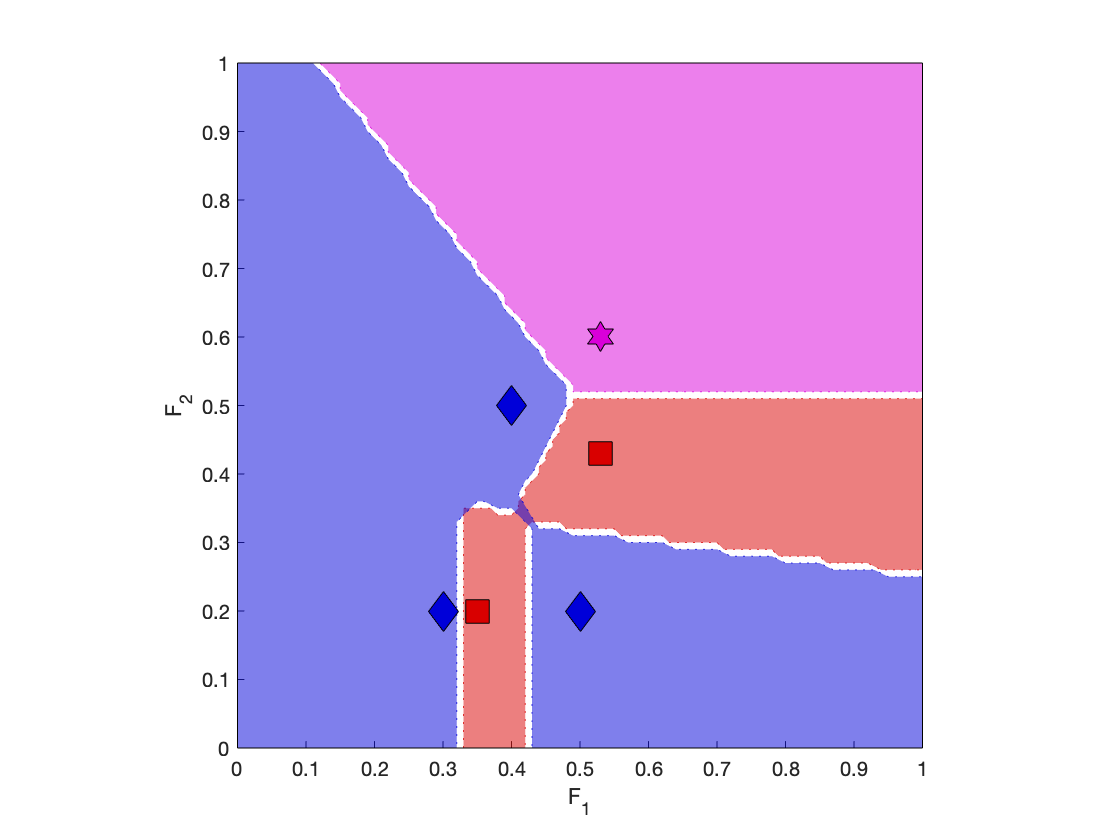

ans =     0.1513    0.4942    0.3319


FM_SHH4.plotZones(0:0.01:1,1,[1 2],1)

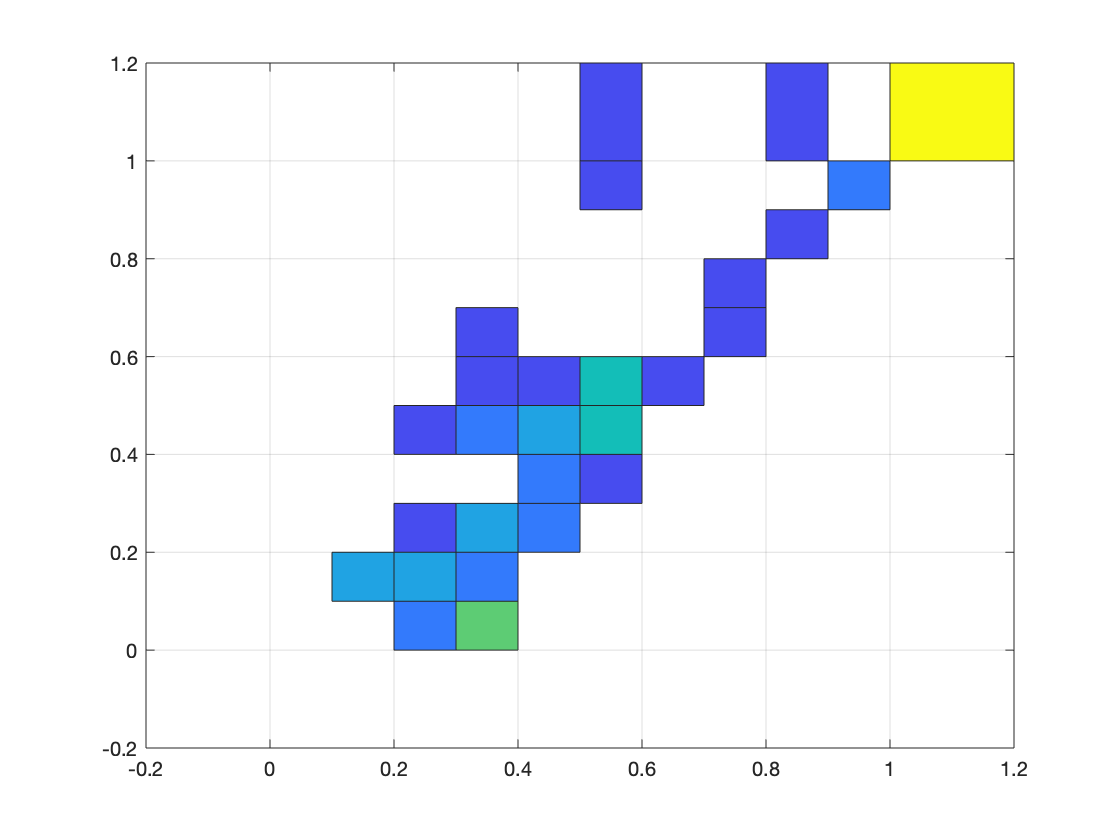

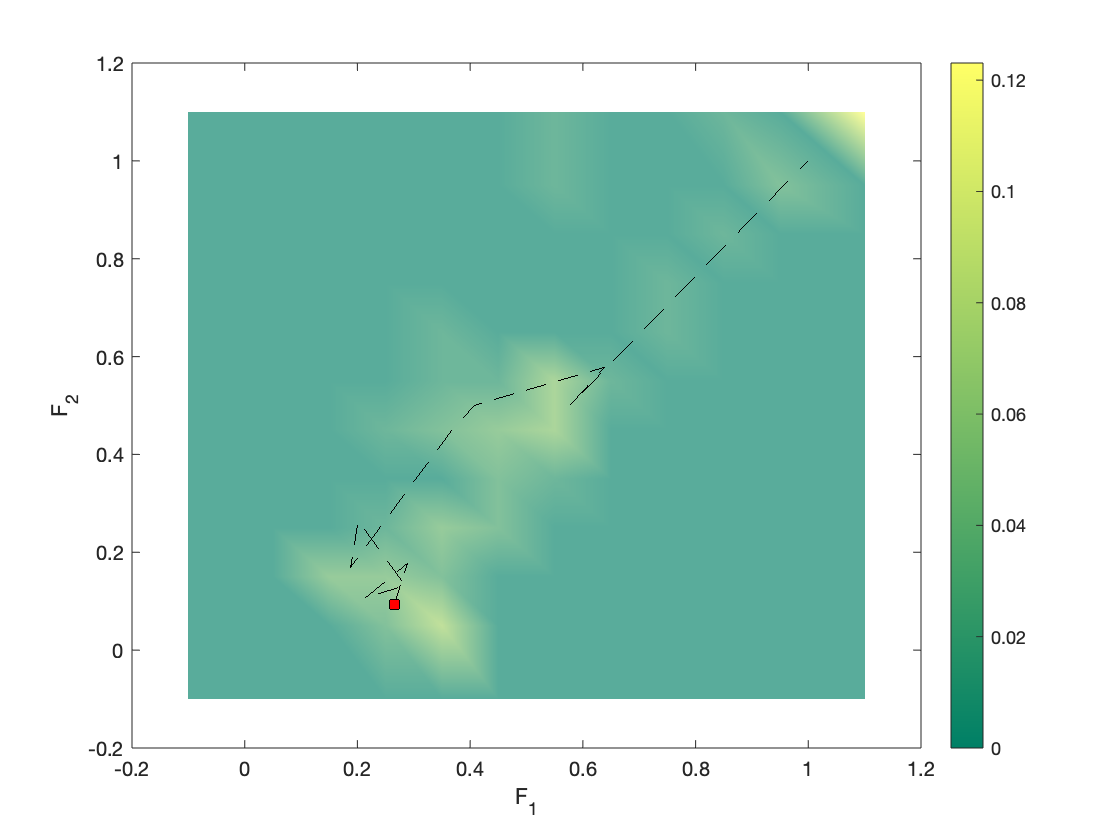

ans =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'interp'
    FaceLighting: 'flat'
       FaceAlpha: 0.6500
           XData: [-0.1000 0.0500 0.1500 0.2500 0.3500 0.4500 0.5500 0.6500 0.7500 0.8500 0.9500 1.1000]
           YData: [-0.1000 0.0500 0.1500 0.2500 0.3500 0.4500 0.5500 0.6500 0.7500 0.8500 0.9500 1.1000]
           ZData: [12×12 double]
           CData: [12×12 double]

  Show all properties


FM_SHH4.plotFeatureMap(InstanceSet,"full",struct('features',[1 2]),true,5)

**Saving all needed files**

save('FM_SHH4','FM_SHH4')
save('FM_Exp5_Results','Results')
